controlSystemDesigner('RC_plant_PI_controller.mat')

%UNCOMPENSATED RC PLANT
R = 10e3;
Ca = 10e-6;
tau = R*Ca;
Fg = 1/(2*pi*tau)

Fg = 1.5915

Fc = 100*Fg  % I initially choose 10 gave too much overshoot

Fc = 159.1549

Tsample = 1/Fc % this also gave me issues 

Tsample = 0.0063

Tsample1 = 0.001 % Final sample time i choose

Tsample1 = 1.0000e-03

G = tf(1,[tau 1]);
Gz = c2d(G,Tsample1,'zoh')


Gz =
 
  0.00995
  --------
  z - 0.99
 
Sample time: 0.001 seconds
Discrete-time transfer function.
Model Properties


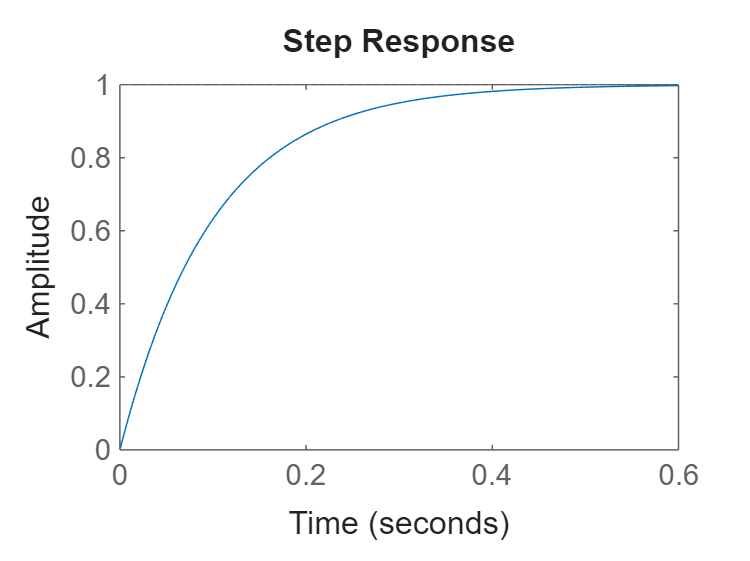

figure(1)
step(G)

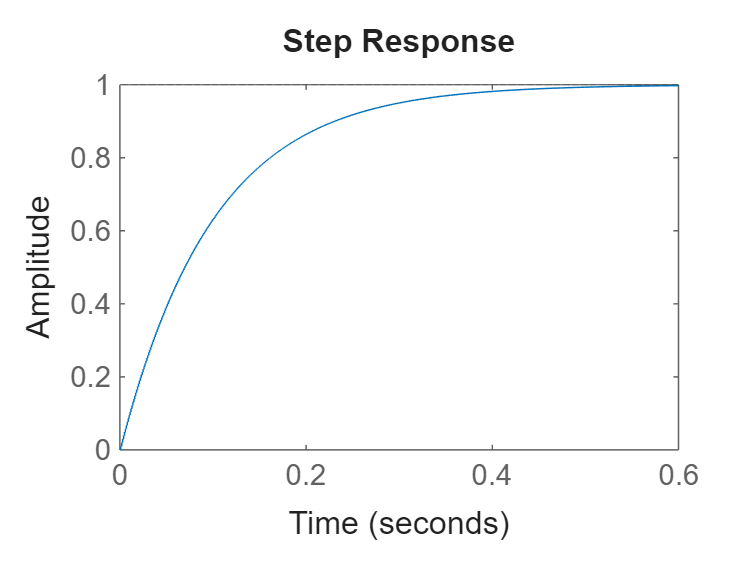

figure(2)
step(Gz)

% sisotool(G)

Gz_PI = c2d(C,Tsample1,'tustin')


Gz_PI =
 
  0.96464 (z-0.982)
  -----------------
        (z-1)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.
Model Properties


Tz = feedback(Gz*Gz_PI,1)


Tz =
 
   0.0095983 (z-0.982)
  ----------------------
  (z^2 - 1.98z + 0.9806)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.
Model Properties


Ts = feedback(G*C,1)


Ts =
 
     9.5598 (s+18.13)
  ----------------------
  (s^2 + 19.56s + 173.3)
 
Continuous-time zero/pole/gain model.
Model Properties


[num den] = tfdata(Gz_PI)

num = 1×1 cell array
    {[0.9646 -0.9473]}


den = 1×1 cell array
    {[1 -1]}


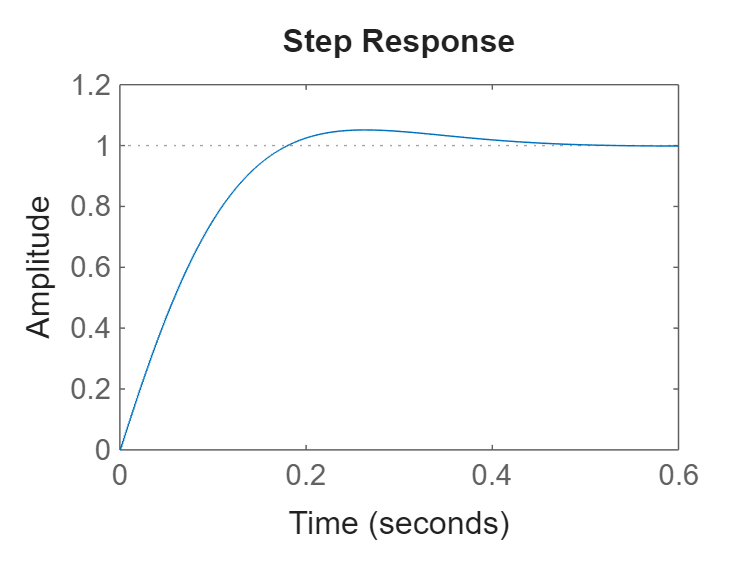

figure(3)
step(Tz)

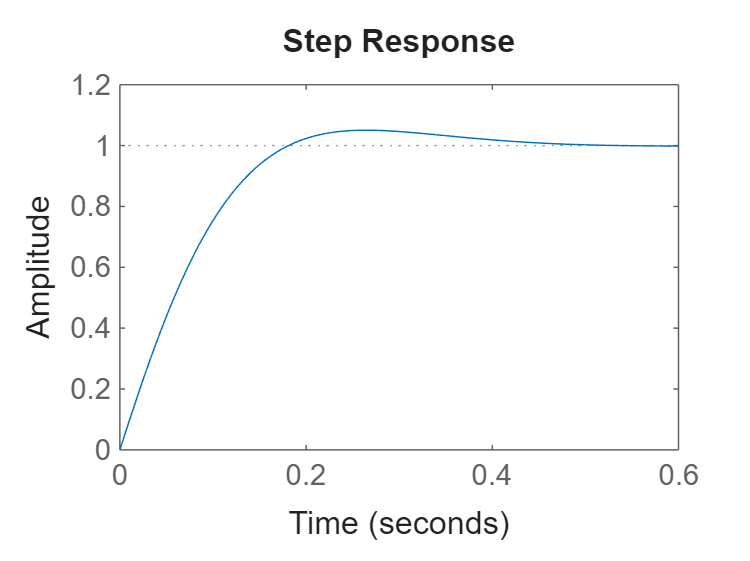

figure(4)
step(Ts)